%{
syms s t 
%First Order
t=0:0.1:50;
H=(s+2)/(s+5) 
n=[1,2];
d=[1 5];
z=roots(n)
p=roots(d)
h=ilaplace(H)
h=matlabFunction(h)
plot(t,h(t))
sysrpk=zpk(z,p,1)
systf=tf(sysrpk)
pzplot(systf)
bode(systf)
%}

%Second Order Low Pass filter
syms s t
t=0:0.001:50;
d=input('Damping Factor = ')

d = 0

a=2*d*0.5;
b=0.25;
H=5./(s^2+s*a+b);
n=5;
d=[1,a,b];
z=roots(n);
p=roots(d)

p =    0.0000 + 0.5000i
   0.0000 - 0.5000i


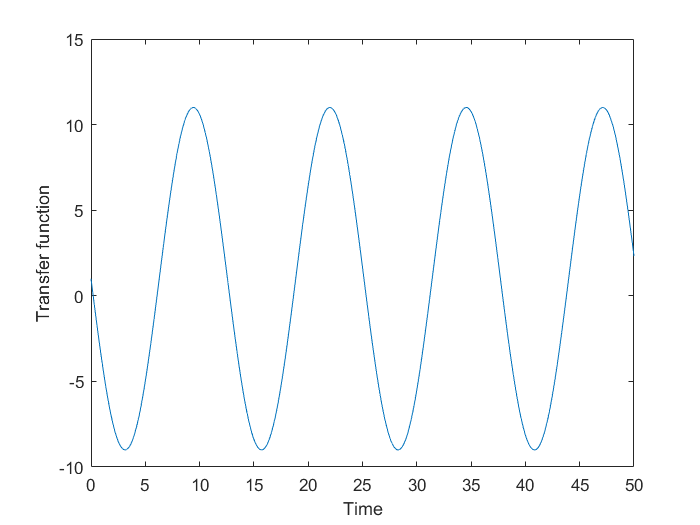

h=matlabFunction(ilaplace(H));
plot(t,1-h(t))
xlabel('Time')
ylabel('Transfer function')

sysrpk=zpk(z,p,1)


sysrpk =
 
       1
  ------------
  (s^2 + 0.25)
 
Continuous-time zero/pole/gain model.



systf=tf(sysrpk)


systf =
 
      1
  ----------
  s^2 + 0.25
 
Continuous-time transfer function.



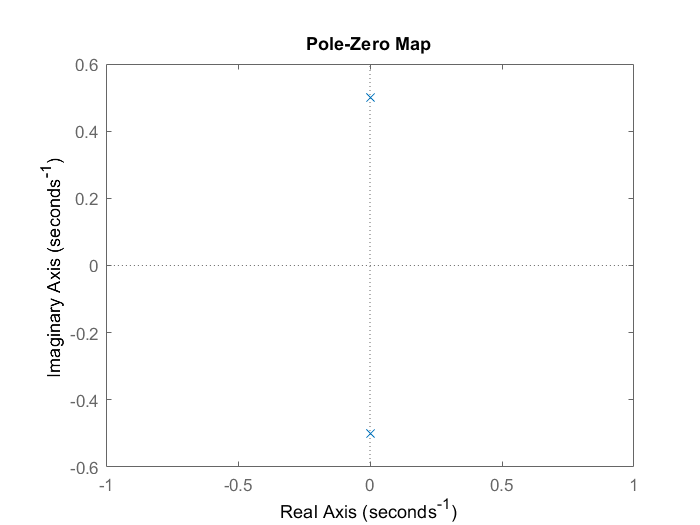

pzplot(systf)

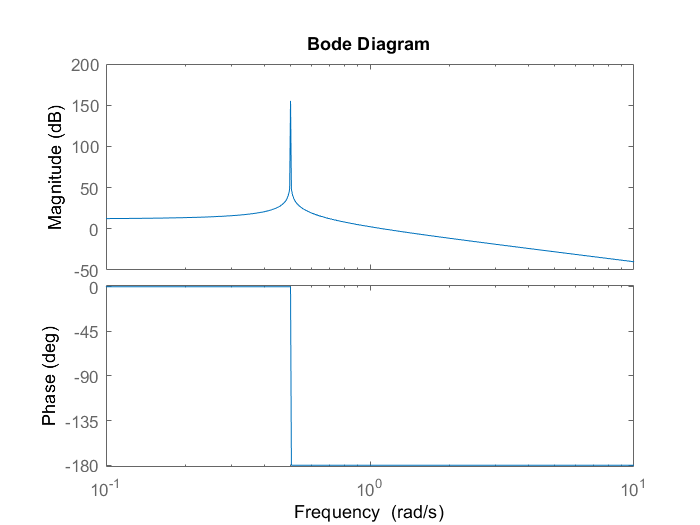

bode(systf)

%Second Order High Pass filter
syms s t
t=0:0.01:100;
d=input('Damping Factor = ')

d = 0.5000

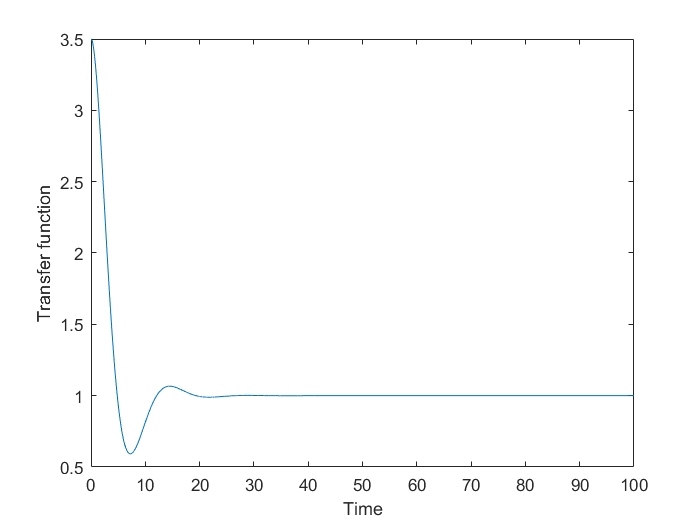

a=2*d*0.5;
b=0.25;
H=5*s^2./(s^2+s*a+b);
n=[5,0,0];
d=[1,a,b];
z=roots(n);
p=roots(d);
h=matlabFunction(ilaplace(H));
plot(t,1-h(t))
xlabel('Time')
ylabel('Transfer function')

sysrpk=zpk(z,p,1)


sysrpk =
 
          s^2
  -------------------
  (s^2 + 0.5s + 0.25)
 
Continuous-time zero/pole/gain model.



systf=tf(sysrpk)


systf =
 
         s^2
  ------------------
  s^2 + 0.5 s + 0.25
 
Continuous-time transfer function.



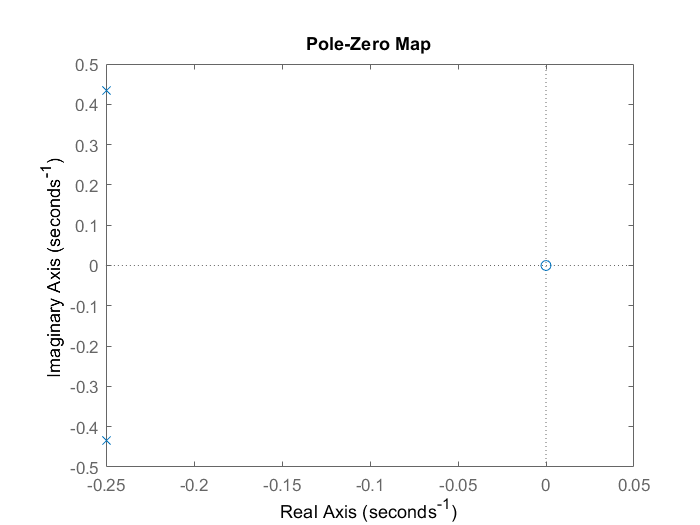

pzplot(systf)

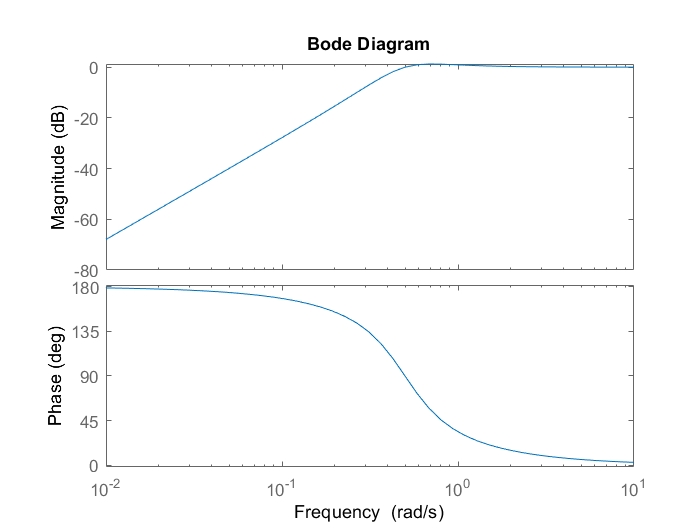

bode(systf)

%Second Order Band Pass filter
syms s t
t=0:0.001:50;
d=input('Damping Factor = ')

d = 1

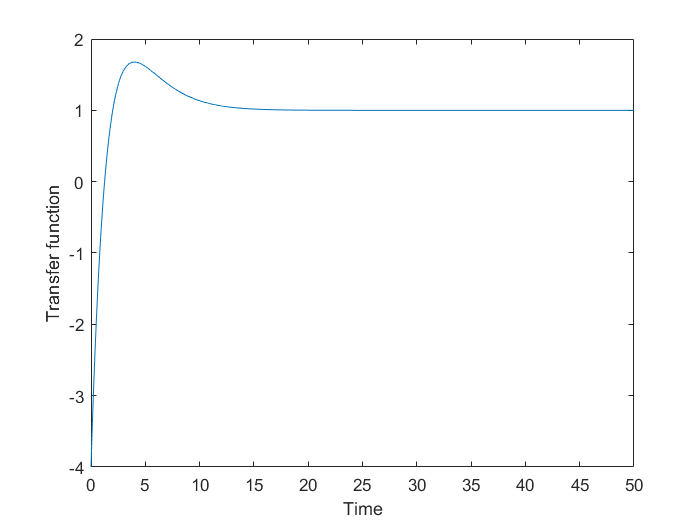

a=2*d*0.5;
b=0.25;
H=5*s./(s^2+s*a+b);
n=[5,0];
d=[1,a,b];
z=roots(n);
p=roots(d);
h=matlabFunction(ilaplace(H));
plot(t,1-h(t))
xlabel('Time')
ylabel('Transfer function')

sysrpk=zpk(z,p,1)


sysrpk =
 
      s
  ---------
  (s+0.5)^2
 
Continuous-time zero/pole/gain model.



systf=tf(sysrpk)


systf =
 
        s
  --------------
  s^2 + s + 0.25
 
Continuous-time transfer function.



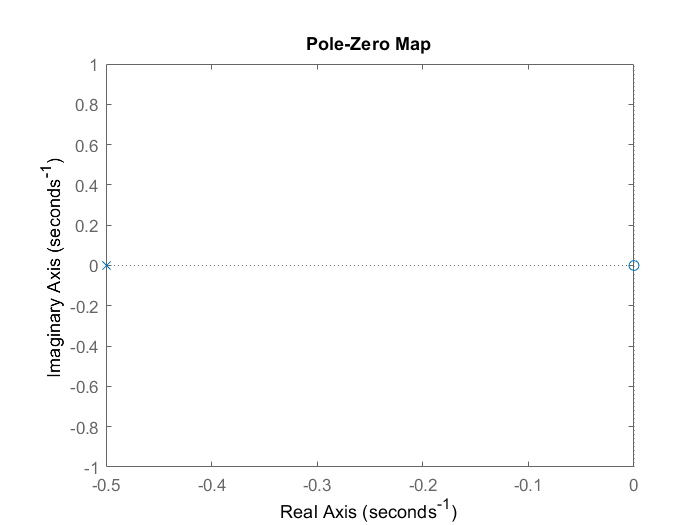

pzplot(systf)

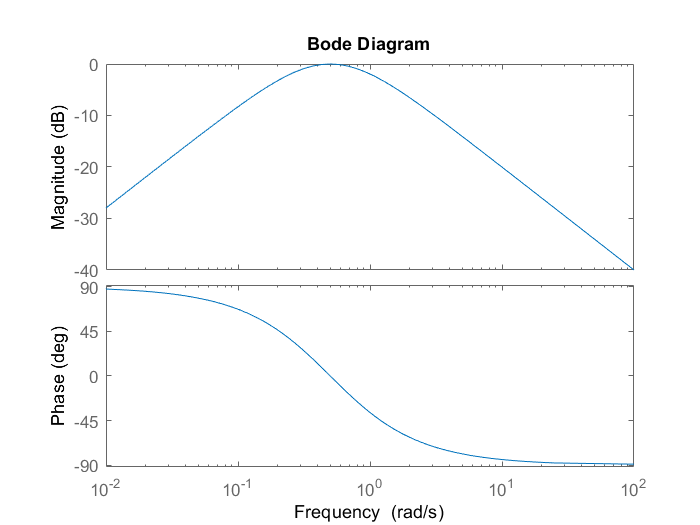

bode(systf)

%Second Order Band Stop filter
syms s t
t=0:0.001:50;
d=input('Damping Factor = ')

d = 1.5000

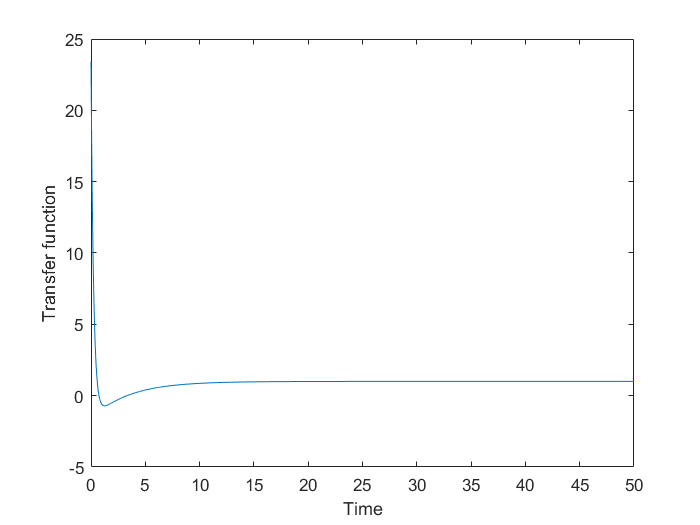

a=2*d*1.5;
b=1.25;
H=(5*s^2+10)./(s^2+s*a+b);
n=[5,0,10];
d=[1,a,b];
z=roots(n);
p=roots(d);
h=matlabFunction(ilaplace(H));
plot(t,1-h(t))
xlabel('Time')
ylabel('Transfer function')

sysrpk=zpk(z,p,1)


sysrpk =
 
       (s^2 + 2)
  --------------------
  (s+4.203) (s+0.2974)
 
Continuous-time zero/pole/gain model.



systf=tf(sysrpk)


systf =
 
       s^2 + 2
  ------------------
  s^2 + 4.5 s + 1.25
 
Continuous-time transfer function.



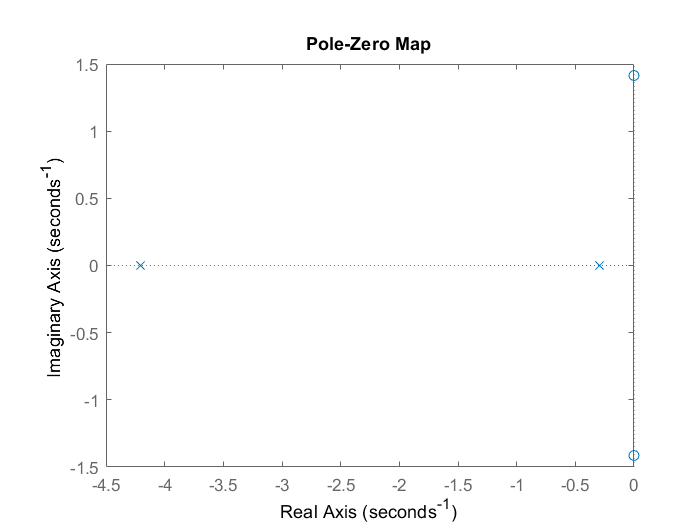

pzplot(systf)

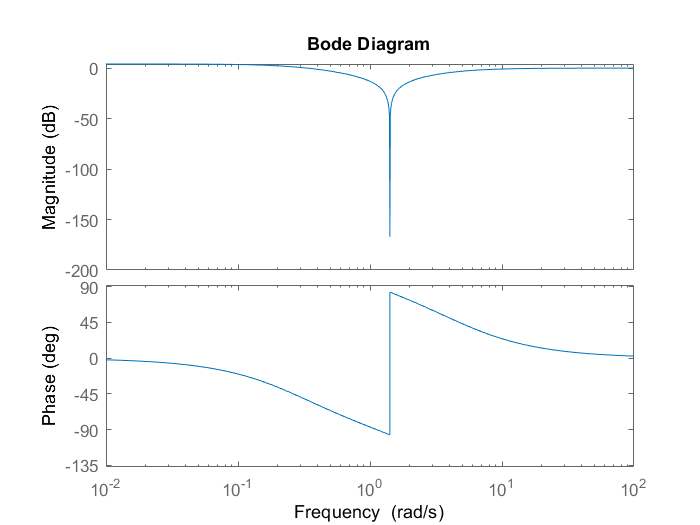

bode(systf)